**Gammatone Spectrogram**

https://uk.mathworks.com/help/audio/ref/gammatonefilterbank-system-object.html

[audio,fs] = audioread('WaveGuideLoopOne-24-96-stereo-10secs.aif');
audio = mean(audio,2);

gammaFiltBank = gammatoneFilterBank('SampleRate',fs, ...
                                    'NumFilters',64, ...
                                    'FrequencyRange',[62.5,20e3]);
audioOut = gammaFiltBank(audio); 

samplesPerFrame = round(0.05*fs);
samplesOverlap = round(0.025*fs);

buff = dsp.AsyncBuffer(numel(audio));
write(buff,audioOut.^2);

sink = dsp.AsyncBuffer(numel(audio));

while buff.NumUnreadSamples > 0
    currentFrame = read(buff,samplesPerFrame,samplesOverlap);
    write(sink,mean(currentFrame,1));
end

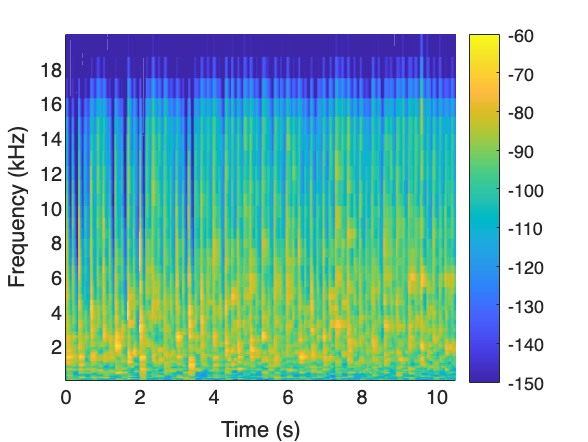

gammatoneSpec = read(sink);
D = 20*log10(gammatoneSpec');

timeVector = ((samplesPerFrame-samplesOverlap)/fs)*(0:size(D,2)-1);
cf = getCenterFrequencies(gammaFiltBank)./1e3;

surf(timeVector,cf,D,'EdgeColor','none')
axis([timeVector(1) timeVector(end) cf(1) cf(end)])
view([0 90])
caxis([-150,-60])
colorbar
xlabel('Time (s)')
ylabel('Frequency (kHz)')